# **Q2. (b)**

## **(i) Lomb-Scale-Periodogram**

**Data Setup**

clear all;
data = readtable("Tesla Stock Price.csv")

data = 2416×2 table
         Date         Close
    ______________    _____

    {'29-06-2010'}    23.89
    {'30-06-2010'}    23.83
    {'01-07-2010'}    21.96
    {'02-07-2010'}     19.2
    {'06-07-2010'}    16.11
    {'07-07-2010'}     15.8
    {'08-07-2010'}    17.46
    {'09-07-2010'}     17.4
    {'12-07-2010'}    17.05
    {'13-07-2010'}    18.14
    {'14-07-2010'}    19.84
    {'15-07-2010'}    19.89
    {'16-07-2010'}    20.64
    {'19-07-2010'}    21.91
    {'20-07-2010'}     20.3
    {'21-07-2010'}    20.22


% Extract features (Xi) and response variable (Yi)
dates = datenum(data.Date, 'dd-mm-yyyy'); % Convert dates to numeric values

% Explicitly set the first date
first_date = dates(1);

X = dates - first_date;
Y = data.Close;

                                                                                                               
% Normalize and Center the closed prices
Y = normalize(Y); 
Y = Y - mean(Y);

% Split data into training and test sets (80% training, 20% test)
train_percentage = 0.8;
train_idx = 1:round(train_percentage * length(dates));
test_idx = (length(train_idx)+1):length(dates);


X_train = dates(train_idx);
X_train = X_train - first_date; %Centering the train data

Y_train = normalize(data.Close(train_idx));
Y_train  = Y_train - mean(Y_train);

X_test = dates(test_idx);
X_test = X_test - first_date; %Centering the test data

Y_test = normalize(data.Close(test_idx));
Y_test = Y_test - mean(Y_test);

% Define Frequencies for Lomb-Scale Periodogram
Fs = 50; % Sampling frequency
N  = length(X_train);

frequencies = linspace(0, Fs/2, 250); % Define frequency range

% Compute Lomb-Scale Periodogram
[frequency, objective_func, a_values, b_values] = lomb_scale_periodogram(Y_train', X_train', frequencies);

Y_pred = sum(a_values.*cos(2*pi*frequency.*X_test) + b_values.*sin(2*pi*frequency.*X_test) , 2)

Y_pred =     0.0190
    0.0129
   -0.0147
   -0.0177
   -0.0195
   -0.0117
   -0.0340
   -0.0492
   -0.0167
   -0.0250


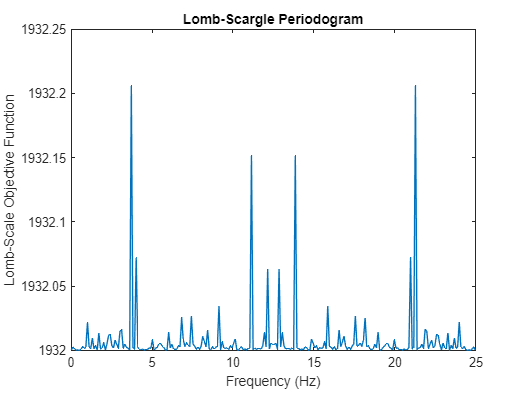


% Plot Lomb-Scale Periodogram
plot(frequency, objective_func);
xlabel('Frequency (Hz)');
ylabel('Lomb-Scale Objective Function');
title('Lomb-Scargle Periodogram');

**Computing the metrics**

[NMSE_train,MAPE_train]=computeMetrics(Y_train, X_train, frequency, a_values,b_values);
[NMSE_test,MAPE_test]=computeMetrics(Y_test, X_test, frequency, a_values,b_values);

disp(['Normalized Mean Square Error (NMSE) for training data: ', num2str(NMSE_train)]);

Normalized Mean Square Error (NMSE) for training data: 0.99481


disp(['Mean Absolute Percentage Error (MAPE) for training data: ', num2str(MAPE_train), '%']);

Mean Absolute Percentage Error (MAPE) for training data: 99.9699%


disp(['Normalized Mean Square Error (NMSE) for test data: ', num2str(NMSE_test)]);

Normalized Mean Square Error (NMSE) for test data: 1.0025


disp(['Mean Absolute Percentage Error (MAPE) for test data: ', num2str(MAPE_test), '%']);

Mean Absolute Percentage Error (MAPE) for test data: 106.3363%


## (b) ARIMA modelling

% Fit the ARIMA model to training data
model = estimate(arima(2,1,2), Y_train);

 
    ARIMA(2,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0034991      0.0025664        1.3634         0.17275
    AR{1}        -0.66121        0.12096       -5.4666      4.5888e-08
    AR{2}        -0.78504        0.11267       -6.9677      3.2222e-12
    MA{1}         0.69327        0.11405        6.0788      1.2109e-09
    MA{2}         0.81203        0.10598         7.662      1.8307e-14
    Variance    0.0019667     3.2496e-05        60.519               0




% Forecast on training data
train_forecast = forecast(model, length(Y_train));

% Evaluate on training data
train_actual_values = Y_train;
train_forecast_values = train_forecast;

% Calculate NMSE on training data
train_NMSE = mean((train_actual_values - train_forecast_values).^2) / var(train_actual_values.^2);

% Calculate MAPE on training data
train_MAPE = mean(abs((train_actual_values - train_forecast_values) ./ train_actual_values)) * 100;

disp(['Training Normalized Mean Square Error (NMSE) using ARMIA: ' num2str(train_NMSE)]);

Training Normalized Mean Square Error (NMSE) using ARMIA: 3.1365


disp(['Training Mean Absolute Percentage Error (MAPE) using ARMIA: ' num2str(train_MAPE)]);

Training Mean Absolute Percentage Error (MAPE) using ARMIA: 308.062



% Forecast on testing data
test_forecast = forecast(model, length(Y_test));

% Evaluate on testing data
test_actual_values = Y_test;
test_forecast_values = test_forecast;

% Calculate NMSE on testing data
test_NMSE = mean((test_actual_values - test_forecast_values).^2) / var(test_actual_values.^2);

% Calculate MAPE on testing data
test_MAPE = mean(abs((test_actual_values - test_forecast_values) ./ test_actual_values)) * 100;

disp(['Testing Normalized Mean Square Error (NMSE) using ARMIA: ' num2str(test_NMSE)]);

Testing Normalized Mean Square Error (NMSE) using ARMIA: 0.11646


disp(['Testing Mean Absolute Percentage Error (MAPE) using ARMIA: ' num2str(test_MAPE)]);

Testing Mean Absolute Percentage Error (MAPE) using ARMIA: 204.3825


**Lomb-Scargle Periodogram:**

**1.Training Performance:**

- The NMSE value of 0.99481 indicates that the Lomb-Scargle model fits the training data quite well.

- However, the MAPE value of 99.9699% is extremely high, indicating that the predictions deviate significantly from the actual values in percentage terms. This suggests that while the model captures the overall variance in the data, it struggles with accurately predicting the actual values.

**2. Testing Performance:**

- The NMSE for the test data is 1.0025, which is close to 1. This indicates that the model's performance on unseen data is similar to its performance on the training data, implying a consistent but mediocre fit.

- The MAPE value of 106.3363% on the test data is also very high, further confirming that the model's predictions are not accurate in terms of percentage error. This suggests that the Lomb-Scargle periodogram may not be the best model for forecasting stock prices in this case.

**ARIMA Model:**

**1.Training Performance:**

- The NMSE value of 3.1365 indicates a poor fit of the ARIMA model to the training data. A higher NMSE value suggests that the model does not capture the variance in the data effectively.

- The MAPE value of 308.062% is extremely high, indicating that the model's predictions are highly inaccurate in terms of percentage error on the training data. This suggests overfitting or potential issues with the model specification.

**2.Testing Performance:**

- The NMSE for the test data is 0.11646, which is much lower than the NMSE for the training data. This indicates that the model generalizes well to unseen data and captures the variance better in the test set.

- However, the MAPE value of 204.3825% on the test data is still extremely high, suggesting that while the model performs better in terms of NMSE, it still struggles with making accurate percentage predictions.

**Conclusion**

**1.Lomb-Scargle Periodogram:**

- The Lomb-Scargle periodogram has consistent NMSE values close to 1 for both training and test datasets, indicating a stable but mediocre fit.

- The extremely high MAPE values for both training and test data suggest that this method is not well-suited for accurately forecasting stock prices in terms of percentage error.

**2. ARIMA Model:**

- The ARIMA model shows a significant discrepancy between training and test NMSE values, indicating possible overfitting or issues with the model on the training set.

- Despite the lower NMSE on the test data, the very high MAPE values indicate that the ARIMA model also struggles with accurate percentage predictions.

**Recommendations**

- **Model Selection:**

- Neither the Lomb-Scargle periodogram nor the ARIMA model provide satisfactory forecasting performance for Tesla stock prices based on the given metrics, particularly in terms of MAPE.

- Data Characteristics: Given the high volatility and irregular sampling of stock prices, advanced models that can handle non-stationary and noisy data may be more appropriate.

**Function Definitions**

function objective_value = L(signal, t, omega, params) %Objective Function
    a = params(1);
    b = params(2);
    objective_value = sum((signal - a*cos(omega*t) - b*sin(omega*t)).^2);
end 

%Gradient Descent
function [a,b] = gradient_descent(signal, t, omega)
    max_iterations = 10000;
    learning_rate = 0.000001;
    params = [0, 0];

    for i = 1:max_iterations
        a = params(1);
        b = params(2);
        
 
        cos_term = cos(omega*t);
        sin_term = sin(omega*t);
        residual = (signal - a*cos_term - b*sin_term);

        gradient_a = 2*sum(sin_term.*residual);
        gradient_b = -2*sum(cos_term.*residual);

        gradient = [gradient_a, gradient_b];

        params = params - learning_rate * gradient;

        % Check termination condition
        if norm(gradient_a) + norm(gradient_b) < 0.0001
%             fprintf('Termination Reached\n');
            break;
        end

    end

    a = params(1);
    b = params(2);

end

%Regression using Lomb-scale Periodogram
function [frequency,objective_func, a_values, b_values] = lomb_scale_periodogram(signal, t, modelling_frequencies)

    % Initialize arrays to store periodogram values
    objective_func = zeros(size(modelling_frequencies));
    
    %a and b values for each modelling frequency
    a_values = zeros(size(modelling_frequencies));
    b_values = zeros(size(modelling_frequencies));

    for i = 1:length(modelling_frequencies)
        omega = 2*pi*modelling_frequencies(i);
        [a, b] = gradient_descent(signal, t, omega);
        a_values(i) = a;    
        b_values(i) = b;

        % Calculate periodogram value for current frequency
        params = [a,b];
        objective_func(i) = L(signal, t, omega, params);
    end
    
    frequency = modelling_frequencies;

end

function [NMSE,MAPE] = computeMetrics(signal, t, frequencies,a_values,b_values)
    %Generating the predicted signal
    y_predicted = sum(a_values.*cos(2*pi*frequencies.*t) + b_values.*sin(2*pi*frequencies.*t) , 2);

    y_error = (signal-y_predicted).^2;

    %NMSE
    NMSE=mean(y_error)/var(signal);
    
    %MAPE
    MAPE= mean(abs((signal-y_predicted)./(signal)))*100;

end